Aerofoil

## **Aerofoil shape**

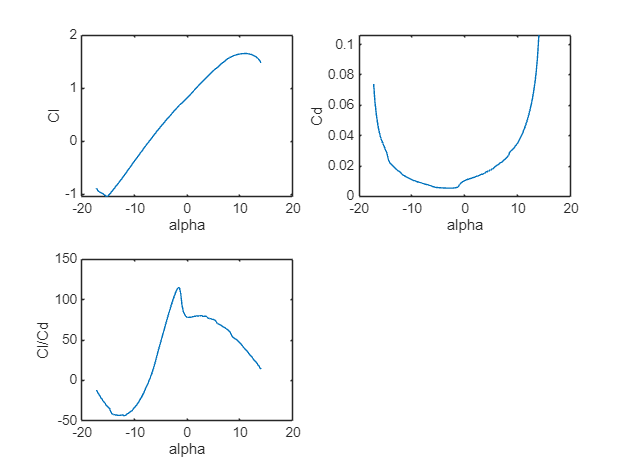

airfoil = Airfoil();
airfoil = airfoil.readPolar("xf-sc21010-il-1000000.csv");
airfoil = airfoil.readShape("sc21010.dat.txt");
airfoil = airfoil.interpShape(9);
figure(1)
clf;
airfoil.plotPolar()


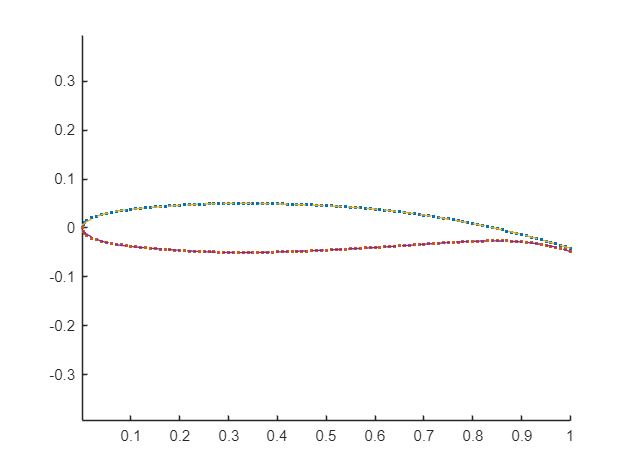

figure(2)
clf;
airfoil.plotShape()


airfoil

Wing Definition:

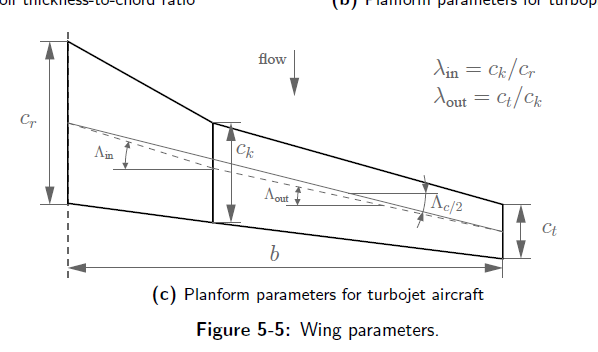

Define wing:

wing = WingGeometry();

airfoil =   Airfoil with properties:

            alpha: [125×1 double]
               Cl: [125×1 double]
               Cd: [125×1 double]
       uppershape: [103×2 double]
       lowershape: [103×2 double]
    upperShapefun: @(x_c)polyval(p_upper,x_c)
    lowerShapefun: @(x_c)polyval(p_lower,x_c)
              x_c: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0261 0.0281 0.0301 0.0321 0.0341 0.0361 0.0381 0.0401 0.0421 0.0441 0.0461 0.0481 0.0501 0.0521 0.0541 0.0561 0.0581 0.0601 … ] (1×500 double)
           t_cfun: @(x_c)polyval(p_thickness,x_c)
              t_c: 0.1007
             x_cm: 0.3246


wing.cr = 11;
wing.ck = 6;
wing.ct = 4;
wing.b = 65/2;
wing.Lambdain50 = 35*pi/180;
wing.Lambdaout50 = 26*pi/180;
wing.yk = wing.b*0.3;
wing = wing.calcSref()
wing.N = 101;
figure(3)
clf;
axis equal
wing.plotWing()

wing =   WingGeometry with properties:

             cr: 11
             ck: 6
             ct: 4
              b: 32.5000
             yk: 9.7500
     Lambdain50: 0.6109
    Lambdaout50: 0.4538
           Sref: 196.6250
              N: []
             Sc: []
         stripy: []
             AR: 5.3719
            Sin: 82.8750
           Sout: 113.7500
             dY: []


wing.c_at_y(10);
wing = wing.createStrips();
wing.plotStrips();
wing = wing.calcSc()

Cruise Condition

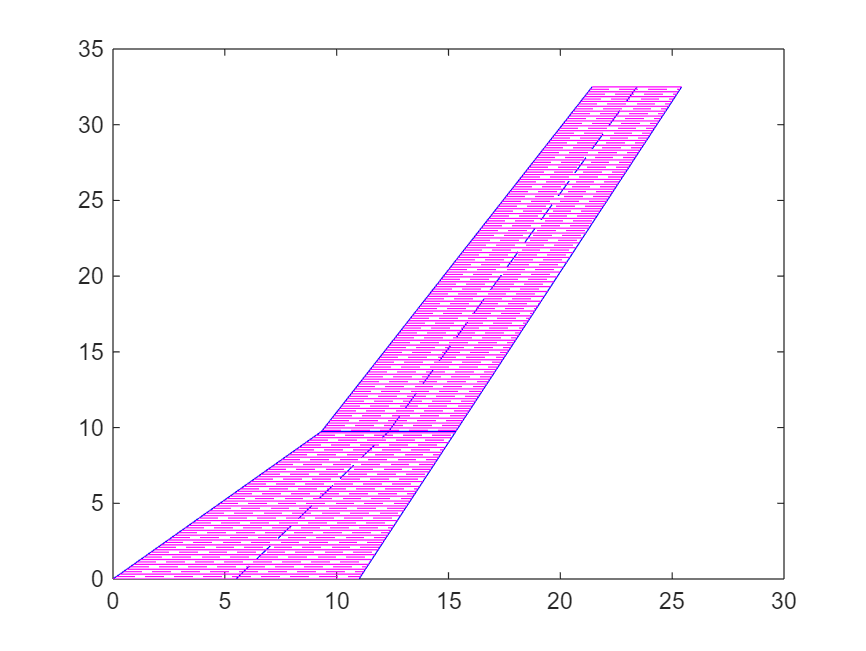

%Chord length
c = 4;
h = convlength(39000, 'ft','m');
[T, a, P, rho, nu, mu] = atmosisa(h);

M = 0.83;

wing =   WingGeometry with properties:

             cr: 11
             ck: 6
             ct: 4
              b: 32.5000
             yk: 9.7500
     Lambdain50: 0.6109
    Lambdaout50: 0.4538
           Sref: 196.6250
              N: 101
             Sc: [1.7565 1.7300 1.7034 1.6769 1.6503 1.6238 1.5972 1.5707 1.5441 1.5176 1.4910 1.4645 1.4379 1.4114 1.3848 1.3583 1.3317 1.3052 1.2786 1.2521 1.2255 1.1990 1.1724 1.1459 1.1193 1.0928 1.0662 1.0397 1.0131 0.9866 0.9677 … ] (1×101 double)
         stripy: [0.1609 0.4827 0.8045 1.1262 1.4480 1.7698 2.0916 2.4134 2.7351 3.0569 3.3787 3.7005 4.0223 4.3441 4.6658 4.9876 5.3094 5.6312 5.9530 6.2748 6.5965 6.9183 7.2401 7.5619 7.8837 8.2054 8.5272 8.8490 9.1708 9.4926 9.8144 … ] (1×101 double)
             AR: 5.3719
            Sin: 82.8750
           Sout: 113.7500
             dY: 0.1609


V = M * a;
Re = rho*V*c/mu

Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;

## Drag Model, Ref15

## Friction Drag

CDF = CDFfun(M, Re, wing, x_cm, t_c, l_d, Swet_SrefWing, Swet_SrefBody)

## Wave Drag

Integration of drag produced by each strip gives the total wave drag coefficient

CDW = CDWfun(wing,@Clfun,M,t_c)

## Wing Weight

W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8
Wpay = 9.81*(W_crew + W_payload)

Wto = 4.3895*1e5*9.81
nult = 3.75; %Chatgpt, b777
range = convlength(7500, 'naut mi','m');

Ww = wingWeightLTH(wing,t_c,Wto)
%Ww = wingWeightHowe(wing,Wpay,Wto,nult,t_c,V,range*1e03)
mw = Ww/9.81 %one wing

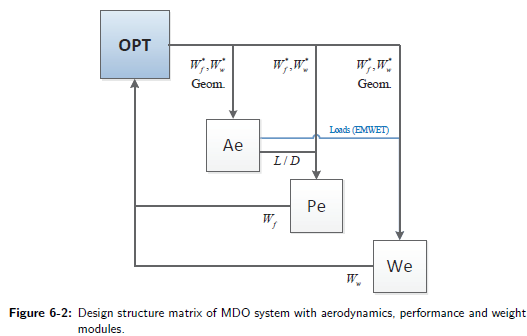

function Cl = Clfun(y)
    Cl = 0.7*y/y;
end